LQR (Observador)

clear all

%constantes

m = 188.6 ; % Massa do ROV
I_z = 40.50 ; %Momento de inércia ao redor Z
m_u = 450.87; %Massa virtual na direção X
m_v = 558.92; %Massa virtual na direção Y
I_r = 239.44; %Momento virtual ao redor de Z

%coeficientes de arrasto hidrodinamico

K_u = 82.30;
K_uu = 309.70;
K_v = 8.50;
K_vv = 505.45;
K_r = 18.21;
K_rr = 94.72;

%velocidades iniciais

U = 0.5;
V = 0.5;
R = 0.126;

Espaço de estados

A = [ -(K_u/m_u)-((2*abs(U)*K_uu)/m_u), ((abs(R)*m_v)/m_u), ((abs(V)*m_v)/m_u);
    -((abs(R)*m_u)/m_v), -(K_v/m_v)-((2*abs(V)*K_vv)/m_v), -((abs(U)*m_u)/m_v);
    ((m_u-m_v)*abs(V)/I_r), ((m_u-m_v)*abs(U)/I_r), -(K_r/I_r)-((2*abs(R)*K_rr)/I_r)];

B = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C = [1,0,0];

D = zeros(1,3);

E = [1/m_u, 0, 0;
     0, 1/m_v, 0;
     0, 0, 1/I_r];

C_id = eye(3);

t_ = 0:0.01:30;
dim= size(t_);
dimT = dim(2);

Controlador LQR

Q = diag([11000,10000,3500]);
R_ = diag([0.01,0.02,0.05]);

K = lqr(A, B, Q, R_);
F = (A-B*K);

Controlador Alocação

polos = [-2.5 + 0.3 * j, -2.5 - 0.3 * j, -1.5];

Kaloc = place(A,B,polos);

Faloc = A-B*Kaloc; 

Para o Observador LQ

Q_obs = diag([1000, 400, 600]);
R_obs = diag(900);

K_obs = lqr(A.', C.', Q_obs, R_obs);
F_obs = (A-K_obs'*C);

Para o Observador por Alocação

polos_obs = [-3 + 0.2 * j, -3 - 0.2 * j, -4.6];

Kaloc_obs = place(A',C',polos_obs);

Faloc_obs = A-Kaloc_obs'*C; 

Descretização e condições iniciais e entradas

x0 = [0;0;0];

u_ = zeros(size(t_));
u = [u_;u_;u_];

Sistema com x e x^

Gamma_LQ = [A-B*K, B*K;
         zeros(3,3), A-K_obs'*C];

Gamma_aloc = [A-B*Kaloc, B*Kaloc;
         zeros(3,3), A-Kaloc_obs'*C];

Bsis = [B;B];

Csis = [eye(6)];

Dsis = [zeros(6,3)];


x_obs = zeros(3, 1);
xch_obs = 0.3*ones(3, 1);
cond_inicial = [x_obs; xch_obs];


sysF = ss(F,B,C,D);%Controlador LQR
sys2 = ss(Gamma_LQ, Bsis, Csis, Dsis); %Observador LQ
sysaloc = ss(Faloc,B,C,D); %Controlador por Alocação
sys4 = ss(Gamma_aloc, Bsis, Csis, Dsis); %Observador aloc

y1 = lsim(sysF, u, t_, x_obs); % controlador LQR
y2 = lsim(sys2, u, t_, cond_inicial); %Observador LQ
y3 = lsim(sysaloc, u, t_, x_obs); %Controlador por Alocação
y4 = lsim(sys4, u, t_, cond_inicial); %Observador Alocação

Plots

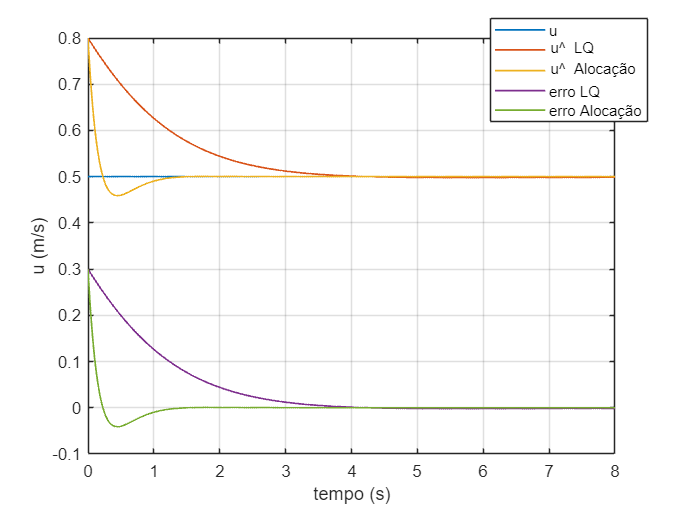

u1 = U + y1(:,1);

u2 = U + y2(:,4);
v2 = V + y2(:, 5);
r2 = R + y2(:, 6);

u3 = U + y3(:,1);

u4 = U + y4(:,4);
v4 = V + y4(:, 5);
r4 = R + y4(:, 6);

e_u = -(u1-u2);
e_u2 = -(u3-u4);


figure(1) 
plot(t_, u1, 'LineWidth', 1) 
hold on
grid on
plot(t_, u2, 'LineWidth', 1)
plot(t_, u4, 'LineWidth', 1)
plot(t_,e_u, 'LineWidth', 1)
plot(t_,e_u2, 'LineWidth', 1)
% title('Velocidade u') 
xlabel('tempo (s)') 
ylabel('u (m/s)')
legend('u', 'u\^ LQ', 'u\^ Alocação', 'erro LQ','erro Alocação') 
xlim ([0 8])
hold off 

legend("Position", [0.77013,0.80139,0.13386,0.12283])

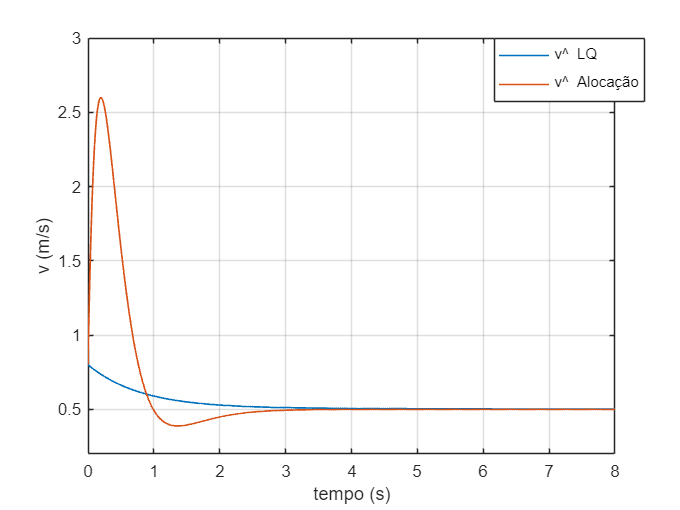



figure(2) 
plot(t_, v2, 'LineWidth', 1) 
hold on
grid on
plot(t_, v4, 'LineWidth', 1) 
% title('Velocidade v') 
xlabel('tempo (s)')
ylabel('v (m/s)') 
legend('v\^ LQ', 'v\^ Alocação') 
xlim ([0 8])
ylim([0.2 3])
hold off 

legend("Position", [0.77013,0.80139,0.13386,0.12283])

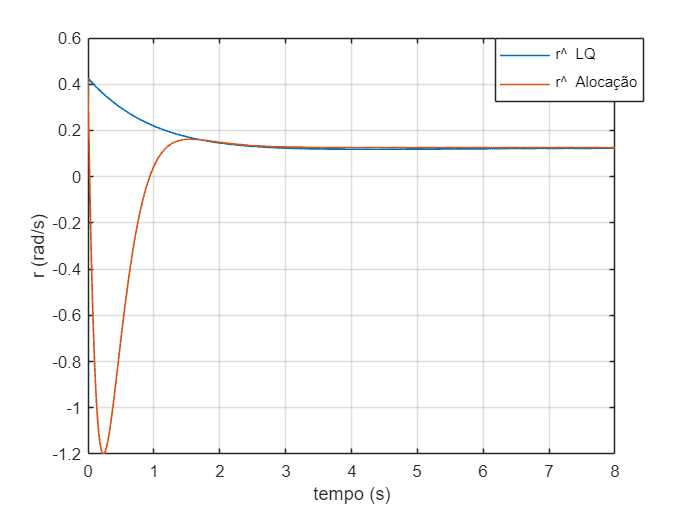



figure(3) 
plot(t_, r2, 'LineWidth', 1)
hold on
grid on
plot(t_, r4, 'LineWidth', 1)
% title('Velocidade r') 
xlabel('tempo (s)')
ylabel('r (rad/s)') 
legend('r\^ LQ', 'r\^ Alocação')
xlim ([0 8])
hold off 
legend("Position", [0.77013,0.80139,0.13386,0.12283])